# An investigation of any external trigger (drinking green tea) on human body using ECG & PPG Signal through feature extraction  (PAT, HR, PWV calculation)  

This scripts is based on pre-processing ECG, PPG, derivatives of PPG, and find some feature extraction- pulse arrival time(PAT), pulse transit time, pulse width velocity, Heart Rate. 

Initially, the raw data-set is collected from different subjects using ecg sensor and ppg sensor via NI-DAQ 601. PPG, ECG were taken before and 30 mins after having external trigger (green tea) from human hands (finger and forearms) for 1 min.  

%sampling rate = 250 Hz     

Pulse Arrival Time (PAT) = Time delay between R-peak of ECG and max value of PPG 1st derivative

HR = No of R - peak of ECG per minutes 

PWV = PAT/ demispan of subject

## Loading ECG

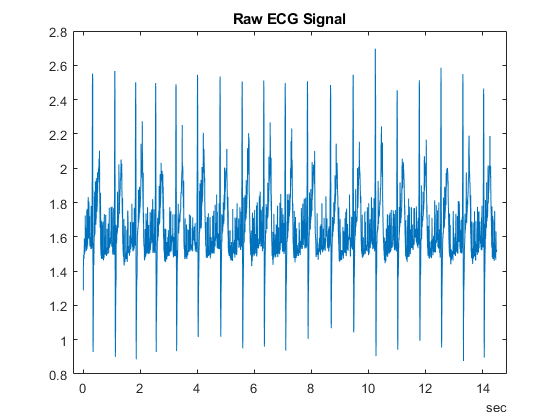

%Loading raw ECG from a subject "s1"
s1_raw_ecg = s21b.Dev1_ai2; %s1_raw_ecg = "ECG data file"
time =  s21b.Time;          %time = "ECG.Time data file" 
figure
plot(time, s1_raw_ecg)       %to plot ECG Vs Time graph 
title("Raw ECG Signal")

## Loading PPG

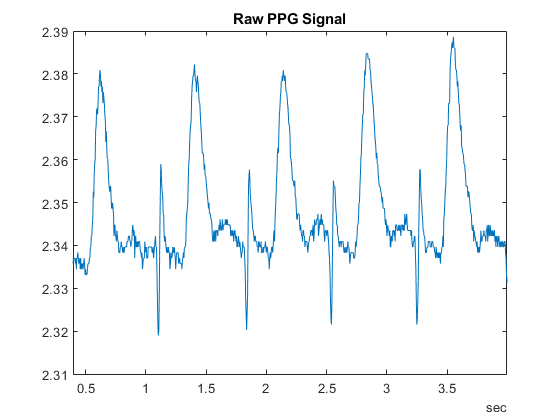

% Loading PPG variables
s1_raw_ppg = s21b.Dev1_ai3;  %s1_raw_ppg = "PPG data file" 

plot(time, s1_raw_ppg);      %to plot PPG Vs Time graph
title("Raw PPG Signal");
xlim([time(100,1) time(1000,1)]);

## Filtering ECG signals

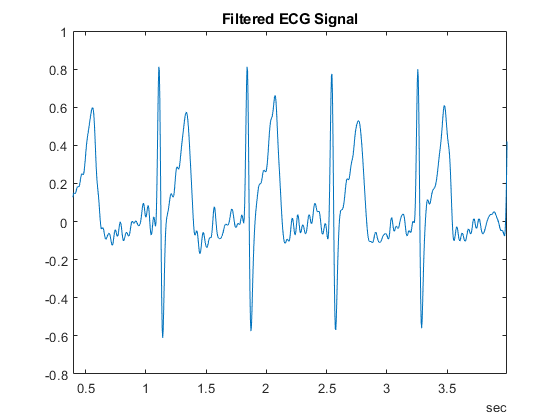

fs1 = 250;   %sampling frequency

%f_ecg ==> after applying low pass filter with cut off frequency 5 Hz & normalizing it   
f_ecg = lowpass(s1_raw_ecg,5,fs1,'Steepness',0.7,'StopbandAttenuation',60);
f_ecg = normalize(f_ecg, 'range', [-1 1]);

%Applying fir filter with cutoff frequency 0.5 Hz
fc = 0.5;
wn= 2*fc/fs1;
bhi = fir1(4,wn,'low',chebwin(5,30));
f_ecg = filter(bhi,1,f_ecg);
 
plot(time, f_ecg)
xlim([time(100,1) time(1000,1)])
title("Filtered ECG Signal")

## Pre-processing PPG signals

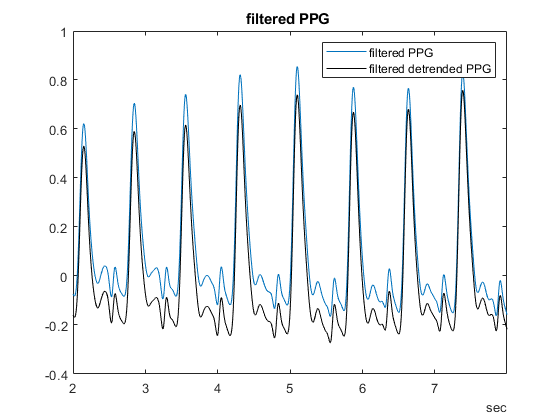

%Applying low-pass & FIR filter & normalizing raw PPG signals 
fc = 0.5;
fs = 250;
wn= 2*fc/fs;
bhi = fir1(14,wn,'low',chebwin(15,30));
f_ppg = filter(bhi,1,s1_raw_ppg);
n_f_ppg = normalize(s1_raw_ppg, 'range', [-1 1]);

%removing trend
detrendedData = detrend(n_f_ppg,6);
%figure
%plot(time, detrendedData)
%hold on
%plot(time, f_ppg, 'k')
%title("Filtered PPG")
%legend("1st Detrended PPG", "1st filtered PPG")
%hold off


%% Smoothing PPG
z = n_f_ppg;            %(500:3000,1);
t = time;               %(500:3000,1);
Smoothed_ppg = smoothdata(z,'gaussian','SmoothingFactor',0.26,'SamplePoints',t);


figure
plot(t, Smoothed_ppg)
hold on
title("filtered PPG ")
detrendedData = detrend(Smoothed_ppg,4);
plot(t, detrendedData, 'k')
legend("filtered PPG", "filtered detrended PPG")

xlim([time(500,1) time(2000,1)])
%ylim([-1.6 -1.5])
hold off

### %PPG 1st Derivative 

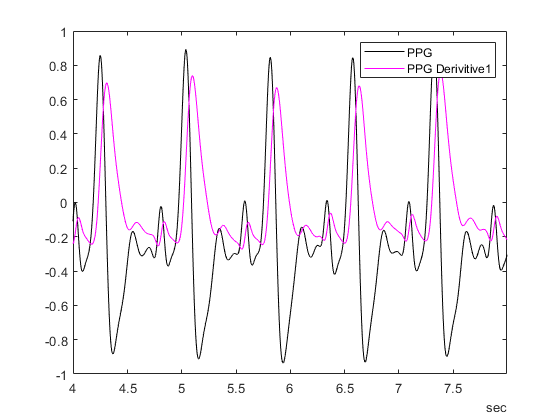

temptime = time((1: length(time) -1), 1); %time for ppg_derivative_1
 
ppg_d1 = diff(detrendedData); %corrected 
fs1 = 250;
ppg_d1 = lowpass(ppg_d1,5,fs1,'Steepness',0.6,'StopbandAttenuation',60);
ppg_d1 = smoothdata(ppg_d1,'gaussian','SmoothingFactor',0.26,'SamplePoints',temptime);
ppg_d1 = normalize(ppg_d1, 'range', [-1, 1]);
figure
plot(temptime, ppg_d1, 'k', "LineWidth", 0.5)
hold on
plot(t, detrendedData, 'm', "LineWidth", 0.5)
legend("PPG", "PPG Derivitive1")
xlim([time(1000,1) time(2000,1)])
hold off

### PPG 2nd Derivative 

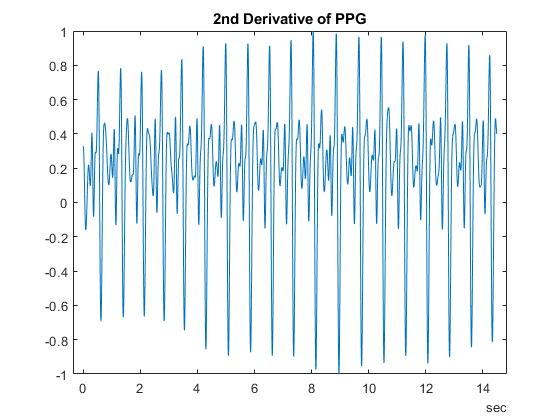

ppg_d2 = diff(ppg_d1);
new_temptime = temptime((1: length(temptime) -1), 1); %time for ppg_derivative_2
ppg_d2 = lowpass(ppg_d2,2,fs1,'Steepness',0.5,'StopbandAttenuation',60);
%d2 = detrend(d2);
ppg_d2 = smoothdata(ppg_d2,'gaussian','SmoothingFactor',0.26,'SamplePoints',new_temptime);
ppg_d2 = normalize(ppg_d2, 'range', [-1, 1]);

plot(new_temptime, ppg_d2)
title("2nd Derivative of PPG") 

#### Plotting PPG and its Derivatives

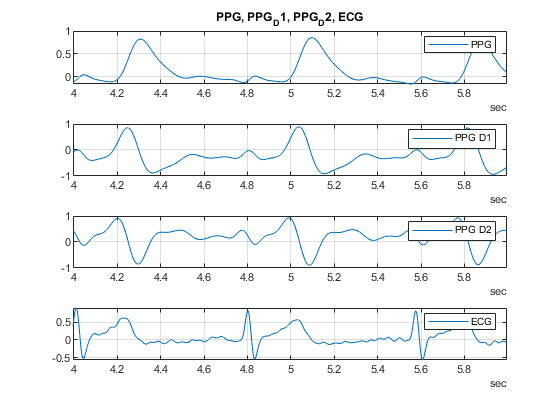

figure
subplot(4,1,1)
plot(time, Smoothed_ppg) 
legend("PPG")
xlim([time(1000,1) time(1500,1)])
title("PPG, PPG_D1, PPG_D2, ECG")
grid on

subplot(4,1,2)
plot(temptime, ppg_d1)
legend("PPG_ D1")
xlim([time(1000,1) time(1500,1)])
grid on

subplot(4,1,3)
plot(new_temptime, ppg_d2)
xlim([time(1000,1) time(1500,1)])
legend("PPG_ D2")
grid on

subplot(4,1,4)
plot(time, f_ecg)
xlim([time(1000,1) time(1500,1)])
legend("ECG")
grid on
hold off

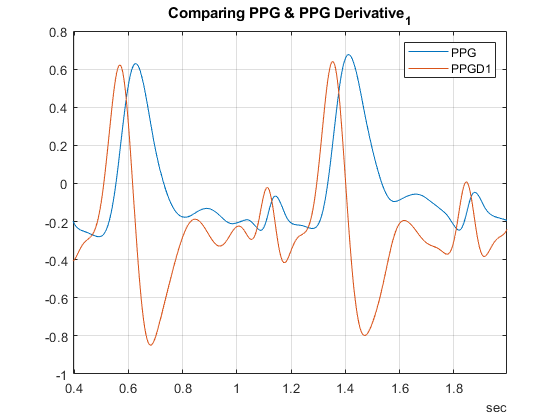

figure
Smoothed_ppg = normalize(Smoothed_ppg, 'range', [-1, 1]); 
plot(time, Smoothed_ppg)
hold on
plot(temptime, ppg_d1)
%plot(new_temptime, d2)
%plot(time, f_ecg1)
xlim([time(100,1) time(500,1)])
legend("PPG", "PPGD1")
grid on
title("Comparing PPG & PPG Derivative_1")
hold off

## Create timetable of PPGs for a stackedplot

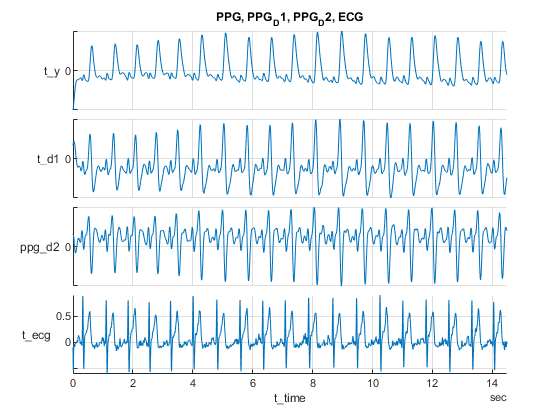

t_time = new_temptime;
t_y = Smoothed_ppg((1:length(Smoothed_ppg)-2), 1);
t_d1 = ppg_d1((1: length(ppg_d1)-1), 1);
t_ecg =f_ecg((1:length(f_ecg) -2), 1); 

TT = timetable(t_time, t_y, t_d1, ppg_d2, t_ecg );

figure
stackedplot(TT) 
grid on
title("PPG, PPG_D1, PPG_D2, ECG")

# Feature Extraction 

## Peak Detection of ECG

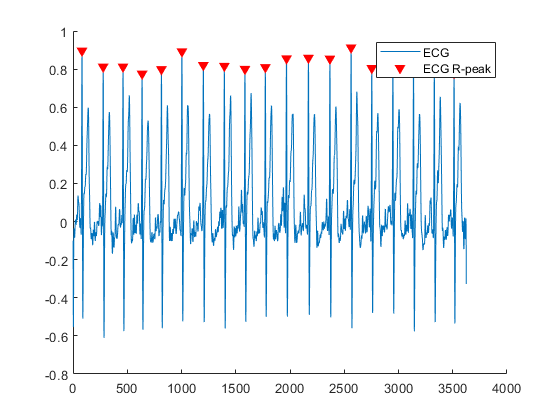

%Detecting R-peak 
tecg = 1:length(f_ecg);
[~,locs_Rwave] = findpeaks(f_ecg,'MinPeakHeight',0.64,...
                                    'MinPeakDistance',120);                               
figure;
hold on 
plot(tecg,f_ecg)
plot(locs_Rwave,f_ecg(locs_Rwave),'rv','MarkerFaceColor','r')
legend('ECG','ECG R-peak') 
hold off

## Peak Detection of PPG:

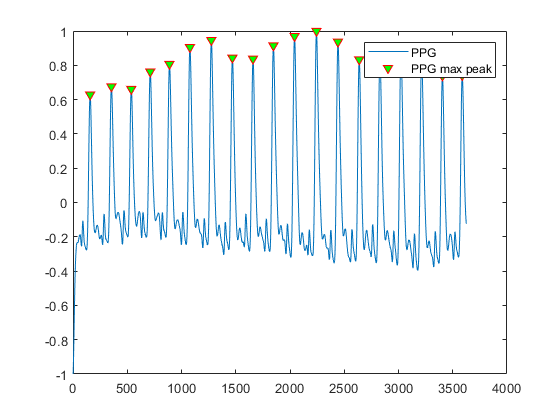

tppg = 1:length(Smoothed_ppg);
[~,locs_max_ppg] = findpeaks(Smoothed_ppg,'MinPeakHeight',0.2,...
                                    'MinPeakDistance',20);                                
figure;
   
plot(tppg,Smoothed_ppg)
hold on 
plot(locs_max_ppg,Smoothed_ppg(locs_max_ppg),'rv','MarkerFaceColor','g')
%axis([0 1000 -1 1])

legend('PPG', 'PPG max peak')
hold off

##  Peak detection of PPG 1st derivative:

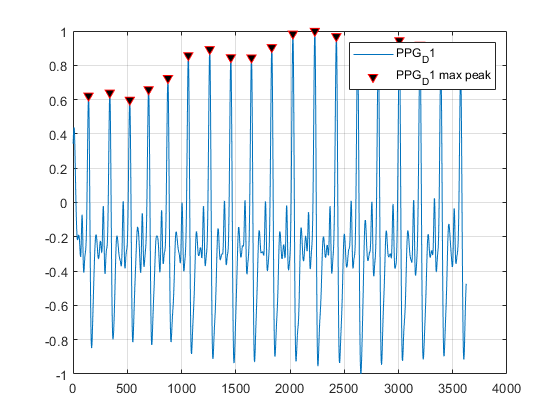

tppgd1 = 1:length(ppg_d1);
[~,locs_max_ppg_d1] = findpeaks(ppg_d1,'MinPeakHeight',0.5,...
                                    'MinPeakDistance',60);
figure 
plot(tppgd1,ppg_d1);
hold on
plot(locs_max_ppg_d1,ppg_d1(locs_max_ppg_d1),'rv','MarkerFaceColor','k')
grid on 
%i = 1: length(locs_max_ppg) + 1;
%locs_max_ppg_d1(i);
hold off
%odd_locs_max_ppg_d1 = locs_max_ppg_d1(i) 


legend('PPG_D1','PPG_D1 max peak');

## peak detection of PPG 2nd Derivative:

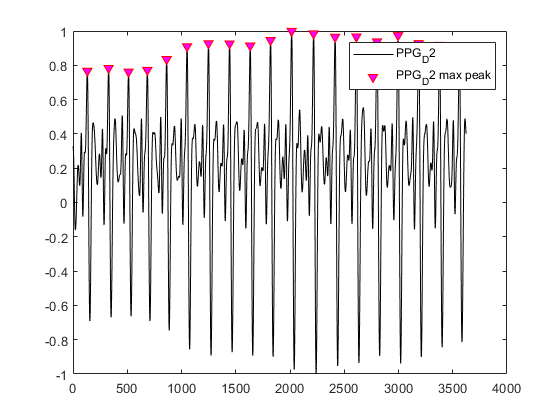

tppgd2 = 1:length(ppg_d2);

[~,locs_max_ppg_d2] = findpeaks(ppg_d2,'MinPeakHeight',0.72,...
                                    'MinPeakDistance',100);             
figure
plot(tppgd2,ppg_d2, 'k');
hold on 
plot(locs_max_ppg_d2,ppg_d2(locs_max_ppg_d2),'rv','MarkerFaceColor','m')
hold off
legend('PPG_D2','PPG_D2 max peak');

## Time_conversion of Peak values

sec = 15 %Reading was choosen for 15 sec

sec = 15

t_ecg = time_converter(locs_Rwave, f_ecg, sec);
t_ppg = time_converter(locs_max_ppg, Smoothed_ppg, sec);
t_ppgd1 = time_converter(locs_max_ppg_d1,ppg_d1, sec);
t_ppgd2 = time_converter(locs_max_ppg_d2,ppg_d2, sec);

%find min value of peak among 4 signals

m_ecg = length(locs_Rwave);
n_ppg = length(locs_max_ppg);
o_ppgd1 = length(locs_max_ppg_d1);
p_ppgd2 = length(locs_max_ppg_d2);
j = [m_ecg n_ppg o_ppgd1 p_ppgd2]

j =     19    19    19    19


i = min(j);

i = 1 : i ;
% PAT Calculation
t_ecg(i);
t_ppg(i);
t_ppgd1(i);
t_ppgd2(i);
PAT1 = abs(t_ecg(i) - t_ppg(i));     % PAT-- from ECG R_peak to PPG max_peak in second
PAT2 = abs(t_ecg(i) - t_ppgd1(i));   % PAT --from ECG R_peak to PPG_D1 max_peak in second
PAT3 = abs(t_ecg(i) - t_ppgd2(i));   % PAT -- from ECG R_peak to PPG_D2 max_peak in second
%PAT4 = abs(t_ecg(i) - t_ppgd2(i));   % PAT-- from ECG R_peak to PPG foot in second  

PAT1_b = mean(PAT1)                % PAT from ECG R_peak to PPG max_peak in second of subject 01

PAT1_b = 0.3088

PAT2_b = mean(PAT2)                % PAT from ECG R_peak to  PPG_D1 max_peak in second of subject 01      

PAT2_b = 0.2500

PAT3_b = mean(PAT3)                % PAT from ECG R_peak to  PPG_D2 max_peak in second of subject 01 

PAT3_b = 0.2041

%PAT4_S1 = mean(PAT4)

# HR Calculation

HR = [length(t_ecg)/sec] *60 %bpm

HR = 76

# PWV Calculation: 

%PWV = PAT2_b / demispan;


%demispan of male/female can be found from the equation
% height of the male person in cm = (1.35* his demispan) +60.1
% height of the female person in cm = (1.40* his demispan) +57.8

## Scattered diagram of PAT

To check the accuracy of mean PAT values  


%find min value of time
t_array = [length(t_ecg) length(t_ppg) length(t_ppgd1) length(t_ppgd2)]

t_array =     19    19    19    19


t_array = min(t_array)

t_array = 19

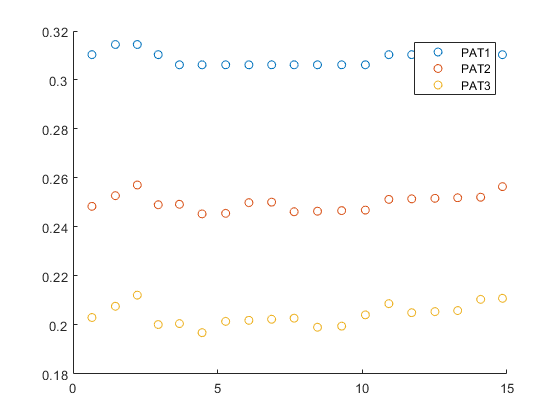

%Scatter plot PAT values Vs Time
for k = 1:i
    if length(t_ppg) == t_array
        s_t = t_ppg; 
    elseif length(t_ppgd1) == t_array    
        s_t = t_ppgd1;
    elseif length(t_ecg) == t_array
        s_t = t_ecg;
    else
        s_t = t_ppgd1
    end
    
end

figure;
hold on 
 
scatter(s_t,PAT1)
scatter(s_t,PAT2)
scatter(s_t,PAT3)
legend("PAT1", "PAT2", "PAT3")